# Ingreso de datos por el usuario y visualización personalizada

El despliegue de información es visualizar por pantalla variables y su contenido. Ahora que ya se conoce acerca de algunos distintos tipos de variables se puede trabajar con las funciones de despliegue de información fácilmente.

## Función `input`

Antes de continuar detengámonos un momento a estudiar la función `input` que es una de las funciones más útiles y relevantes dentro de la programación. La función `input` permite que el usuario ingrese información.

Esta función muestra un mensaje, espera a que el usuario ingrese un valor y presione le tecla intro (o "enter").

**La entrada de información siempre se realiza mediante la ventana de comandos (Command Window)**.

% Ingrese su código aquí :)

#### Observación

En esencia no es necesario utilizar la función `input` con el segundo argumento `"s"` para ingresar un texto.

% Ingrese su código aquí :)

La diferencia radica en que el argumento `"s"` le indica a la función `input` que se ingresará una cadena o un arreglo de caracteres, por lo que no es necesario utilizar comillas simples `''` (apóstrofes) o comillas dobles `""` entre el texto a ingresar. Caso contrario, la función `input` continuará solicitando una nueva entrada válida.

## Funciones de despliegue de información

Las funciones de despliegue de información nos permite configurar y detallar cómo verá el usuario la información. Empecemos con la más sencilla de las funciones de despliegue.

### Función `disp`

La función `disp` permite desplegar, o visualizar, únicamente el contenido de una variable. 

% Ingrese su código aquí :)

De esta forma es posible personalizar la salida de información.

% Ingrese su código aquí :)

#### Observación

No necesariamente se debe guardar el contenido de una variable en una variable, valga la redundancia, para pasarle como argumento a la función `disp`. También es posible pasarle como argumento directamente el contenido que se desea desplegar.

% Ingrese su código aquí :)

Sin embargo, se recomienda crear variables para los mensajes de salida puesto que es más sencillo modificar éstos dentro de una variable que buscar dónde está el `disp` que los está desplegando. Esto es especialmente útil cuando crece el código, además que se podría utilizar el mismo mensaje en diferentes `disp` en lugar de estar copiando en cada ocasión el mensaje como argumento de esta función.

### Función `sprintf`

La función `sprintf` permite dar formato a los datos usando operadores de formato determinados.

Para explicar cómo utilizar la función `sprintf` podemos basarnos en la siguiente imagen.

**Figura 1.** Operadores para especificar el formato.

*Tomado de la documentación oficial de MATLAB.*

Observemos que el formato consta de diferentes partes, pero las dos obligatorias son: iniciar el formato con el operador de formato (que está representado por el símbolo de porcentaje) y cerrar el formato con el operador caracter de conversión.

Opcionalmente se pueden ingresar los siguientes operadores: identificador, banderas o caracteres de relleno, ancho del campo, precisión y subtipo.

Como se puede observar, podemos controlar la salida tanto como queramos y necesitemos. A continuación se listan los caracteres de conversión disponibles.

**Figura 2.** Operadores de conversión.

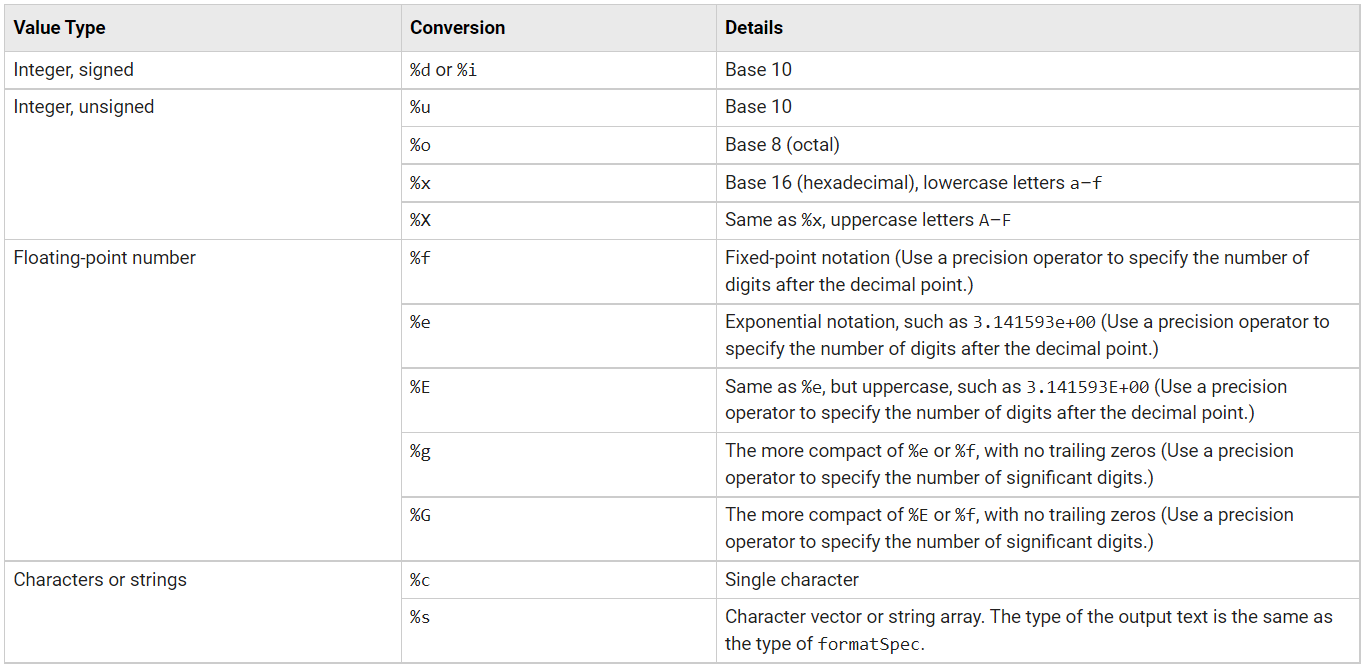

*Tomado de la documentación oficial de MATLAB.*

Entre los caracteres de conversión que podemos destacar por su uso frecuente son:

- Para números enteros con signo: `%d` o `%i`

- Para números enteros sin signo: `%u`

- Para números de punto flotante: `%f`

- Para un sólo caracter: `%c`

- Para cadenas: `%s`

% Ingrese su código aquí :)

Con los ejemplos anteriores no es necesario indicar la precisión puesto que no tienen. La precisión se la puede indicar con números de punto flotante.

% Ingrese su código aquí :)

Notemos que el decimal es redondeado. Este redondeo es únicamente para la visualización, no afecta a la variable original. Además, el redondeo se realiza con las reglas tradicionales de redondeo: utilizando el anterior número y tomando como referencia el número 5 para aplicar o no el redondeo.

También es importante hablar de los caracteres especiales dentro de MATLAB, los cuales se encuentran listados junto con su representación en la siguiente tabla.

**Figura 3.** Caracteres especiales.

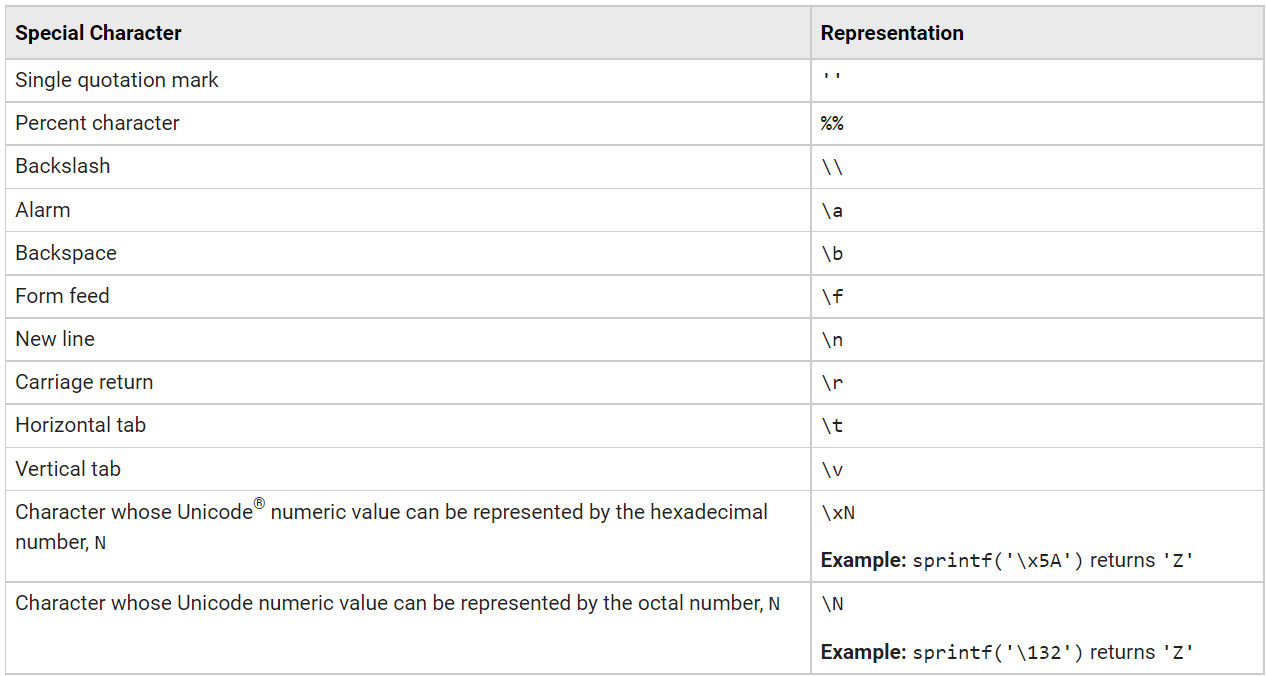

*Tomado de la documentación oficial de MATLAB.*

Estos caracteres pueden ser insertados en cualquier parte de la cadena de especificaciones de formato. Son de bastante utilidad para controlar aún más el despliegue de información, controlar el espaciamiento del texto, los saltos de líneas, etc.

Además, notemos que si se desea insertar un símbolo como porcentaje o división izquiera (*backslash* `\`), entonces el símbolo debe escribirse dos veces.

% Ingrese su código aquí :)

### Función `fprintf`

La función `fprintf` es extremadamente similar a la función `sprintf`. En cuanto a la aplicación, la función `fprintf` se puede utilizar con propósitos muy específicos, pero a breves rasgos la diferencia con la función `sprintf` es que la función `fprintf` no tiene salida, por ende, despliega el texto tal como lo hace la función `disp` en lugar de asignar la salida a la variable por defecto `ans`.

% Ingrese su código aquí :)

#### Observación

Otra diferencia no despreciable es que la función `fprintf` requiere un salto de línea al final de la cadena de especificaciones de formato para que la transición al siguiente código sea adecuada. Esto se visualiza más fácilmente en la ventana de comandos.

### Ejercicio

Los ingenieros usan regularmente unidades tanto inglesas como SI (Système International d’Unités). Algunos campos usan principalmente uno u otro, pero muchos combinan los dos sistemas. Por ejemplo, la tasa de entrada de energía a una planta de potencia de vapor a partir de la quema de combustibles fósiles usualmente se mide en $\mathrm{Btu}/\mathrm{hora}$. Sin embargo, la electricidad producida por la misma planta, por lo general, se mide en $\mathrm{joules}/\mathrm{s}\;\left(\mathrm{watts}\right)$. En contraste, los motores de automóvil con frecuencia se califican en caballos de fuerza o en pie ${\mathrm{lb}}_{\mathrm{f}} /\mathrm{s}$. He aquí algunos factores de conversión que relacionan estas diferentes mediciones de potencia:


$$1\;\mathrm{kW}=3412\ldotp 14\;\mathrm{Btu}/\mathrm{h}=737\ldotp 56\;\mathrm{ft}\cdot {\mathrm{lb}}_{\mathrm{f}} /\mathrm{s}$$



$$1\;\mathrm{hp}=550\;\mathrm{ft}\cdot {\mathrm{lb}}_{\mathrm{f}} /\mathrm{s}=2544\ldotp 5\;\mathrm{Btu}/\mathrm{h}$$


- Genere una tabla de conversiones de $\mathrm{kW}$ a $\mathrm{hp}$. La tabla debe comenzar en $0\;\mathrm{kW}$ y terminar en $15\;\mathrm{kW}$. Use la función `input` para permitir al usuario definir el incremento entre entradas de la tabla. Use `disp` y `fprintf` para crear una tabla con un título, encabezados de columna y espaciamiento apropiado.

- Genere una tabla de conversiones de $\mathrm{ft}\cdot {\mathrm{lb}}_{\mathrm{f}} /\mathrm{s}$ a $\mathrm{Btu}/\mathrm{h}$. La tabla debe comenzar en $0\;\mathrm{ft}\cdot {\mathrm{lb}}_{\mathrm{f}} /\mathrm{s}$, pero permitir al usuario definir el incremento entre entradas de tabla y el valor final de la tabla. Use `disp` y `fprintf` para crear una tabla con un título, encabezados de columna y espaciamiento apropiado.

- Genere una tabla que incluya conversiones de $\mathrm{kW}$ a $\mathrm{Btu}/\mathrm{h}$ y $\mathrm{ft}\cdot {\mathrm{lb}}_{\mathrm{f}} /\mathrm{s}$. Permita al usuario definir el valor inicial de $\mathrm{kW}$, el valor final de $\mathrm{kW}$ y el número de entradas en la tabla. Use `disp` y `fprintf` para crear una tabla con un título, encabezados de columna y espaciamiento apropiado.

*Ejercicio tomado de Moore, 2007.*

### Solución

% Ingrese su solución aquí :)

## Material adicional

- [Dar formato al texto](https://www.mathworks.com/help/matlab/matlab_prog/formatting-strings.html)